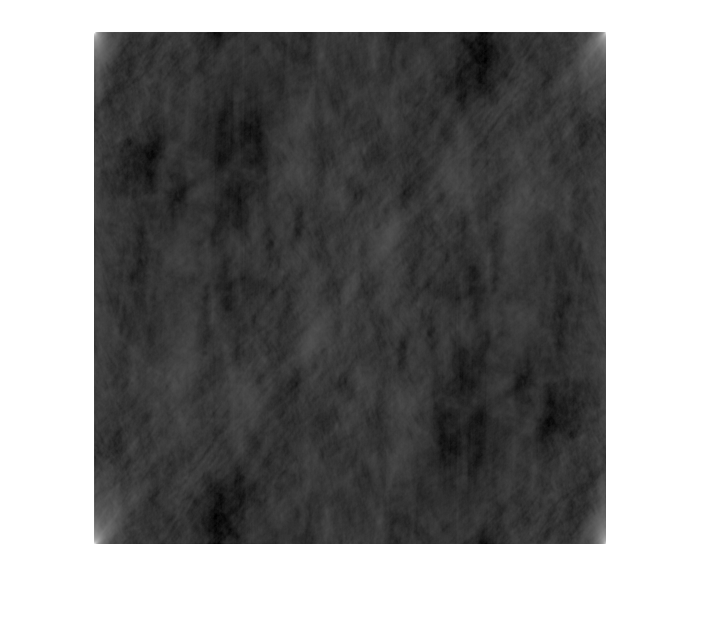

% B8
clear
img = imread("lenaG.bmp");
img = im2double(img);
img_fft = fft2(img);

img_fft = abs(real(img_fft)) + 0i; %phase to 0
% img_fft = abs(img_fft) + 0i; %phase to 0

img_ifft = ifft2(img_fft);
imshow(log(img_ifft),[])